clearvars
x1 = 5 
x2 = 4.5 
x3 = 3.5 

x = [x1, x2, x3]
x_mean = ones(1,3)*mean(x)
x_Ex = x - x_mean
quiver3(0,0,0,x(1), x(2), x(3))
hold on 
quiver3(0,0,0,x_mean(1), x_mean(2), x_mean(3))
quiver3(0,0,0,x_Ex(1), x_Ex(2), x_Ex(3))
hold off

% ax = draw_vector([],'title','vector',"vector",x, x_mean, x_Ex)
% ax.XLim = [-15,15]
% ax.YLim = [-15,15]
% ax.ZLim = [-15,15]

% % s = rng(1)
N = 500;
Population = randn(1,N*10)'+1;



% fill sample matrix
vectors = zeros(N,3);
for i = 1:N
    vectors(i,:) = randsample(Population,3);
end
vectors = vectors';

%fill mean sample matrix
vectors_mean = zeros(N,3);
for i = 1:N
    vectors_mean(i,:) = mean(vectors(:,i))*ones(1,3);
end
vectors_mean = vectors_mean';

%fill sample - mean_sample matrix
v_Ev = vectors - vectors_mean;



X = cell(1, N);
[X{:}] = extract(v_Ev); % ВЕКТОР ОШИБОК
ax = draw_vector([],'title','vectors', 'vector',X{:});

fig162


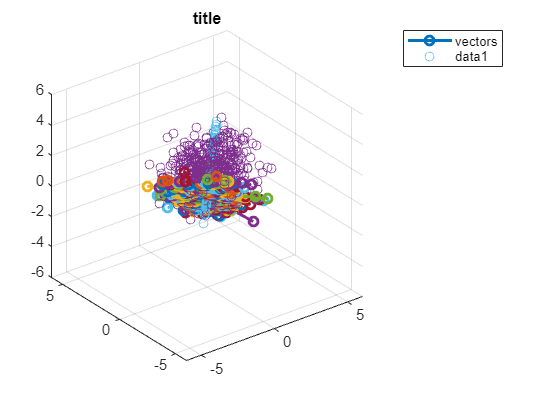


hold(ax,"on");
ax = draw_vector([ax],'title','vectors', 'point',vectors);

ax = draw_vector(ax,'title','vectors', 'vector',mean(Population)*ones(1,3));
ax = draw_vector(ax,'title','vectors', 'point',vectors_mean);
ax.XLim = [-6,6];
ax.YLim = [-6,6];
ax.ZLim = [-6,6];

function [varargout] = extract(A)
    for i = 1:length(A)
        varargout{i} = A(:,i);
    end
end



function [bpar,bper,ang] = projection_matrix(A,b)
% функция считает угол между вектором и пространством столбцов матрицы A
    for ii =1:size(A,2)
        A(:,ii) = A(:,ii)/norm(A(:,ii));
    end
    beta = A*transpose(A)*b;
    beta = beta/norm(beta); % нормируем вектор beta
    Pbeta = beta*transpose(beta); % оператор проектирования вектора на 
    bpar = Pbeta*b;
    bper = b-bpar;
    ang = rad2deg(acos(norm(bpar)/norm(b)));
end

function ax = draw_vector(ax,ttl,names,type,varargin)
% функция строит двух- и трех-мерные вектора, а также рассеянные данные из
% матрицы
% ax - оси (если пустые, то создаются новые)
% ttl - заголовок картинки
% names - имена векторов
% type:
%       "vector" - аргументы, которые передаются после интерпретируются
%                   как отдельные вектора
%       "point"  - в этом случае передается матрица в качестве аргумента и
%       столбцы матрицы строятся при помощи функций scatter и scatter3 d
%       в зависимости от размерности массива
    arguments
        ax =[]
        ttl string =strings(0,1)
        names string =strings(0,1)
        type string {mustBeMember(type,["vector" "point"])}="vector"
    end
    arguments (Repeating)
        varargin double
    end
    was_empty = isempty(ax); % это признак того, что все строится на новых осях
    if was_empty
        ax = get_next_ax();
    else
        hold(ax,"on");
        % if ~isempty(ax.Legend)
        %     leg_before = ax.Legend.String;
        % else
        %     leg_before = strings(0,1);
        % end
    end
    
    if strcmp(type,"vector")
        is_3D = numel(varargin{1})==3;
            if is_3D
                [x,y,z]  = make_xy(varargin{1});
                plot3(ax,x,y,z,'LineWidth',2,'Marker','o');
                hold on 
                for iii = 2:numel(varargin)
                        [x,y,z] = make_xy(varargin{iii});
                        plot3(ax,x,y,z,'LineWidth',2,'Marker','o');
                end
                grid on
                hold off                
            else
                [x,y]  = make_xy(varargin{1});
                plot(ax,x,y,'LineWidth',2,'Marker','o');
                hold on 
                for iii = 2:numel(varargin)
                        [x,y]  = make_xy(varargin{iii});
                        plot(ax,x,y,'LineWidth',2,'Marker','o');
                end
                grid on
                hold off
            end
            if isempty(names)||(numel(names)~=numel(varargin))
                legend(ax,string(1:numel(varargin)));
                
            else
                % if ~was_empty
                %      names= [names(:);leg_before(:)];
                % end
                legend(ax,names);
            end
            xlim(ax,[-1 1]);
            ylim(ax,[-1 1]);
            if ~isempty(ttl)
                title(ax,ttl);
            end
    else
        %data_number = numel(varargin); % число массивов данных
        is_3D = size(varargin{1},1)==3;
        data = varargin{1};
        if size(data,2)>1
            data = transpose(data);
            is_transpose = true;
        else
            is_transpose = false;
        end
        if ~is_transpose
            for iii = 2:numel(varargin)
                data = [data,varargin{iii}];
            end
        else
            for iii = 2:numel(varargin)
                data = [data,transpose(varargin{iii})];
            end            
        end

        if is_3D
            scatter3(ax,data(:,1),data(:,2),data(:,3));
        else
            scatter(ax,data(:,1),data(:,2));
        end

    end
    if ~was_empty
            hold(ax,"off");
    end
end
function [x,y,z]  = make_xy(col)
% добавляет к координатам вектора нули так, чтобы при помощи функции plot
% строилась линия
    switch numel(col)
        case 1
            x = [col(1)];
            y = 0;
            z = 0;
        case 2
            x = [0 col(1)];
            y = [0 col(2)];
            z = zeros(1,2);
        case 3
            x = [0 col(1)];
            y = [0 col(2)];
            z = [0 col(3)];
    end
end